% Manuelle LAB-Pixelanalyse für eine einzelne Schildkategorie
% Ablauf: 1. Ordner einer Schildkategorie auswählen. 2. In jedem Bild charakteristische Schildpixel anklicken. 3. Aus allen markierten Pixeln werden LAB-Verteilungen, Perzentilgrenzen und Diagramme erzeugt.
% Bedienung im Bild: Linksklick = Pixel markieren Rechtsklick = letzte Markierung entfernen Backspace = letzte Markierung entfernen R = alle Markierungen im aktuellen Bild löschen Enter = aktuelles Bild abschließen N = aktuelles Bild ohne Pixel überspringen Q = Verarbeitung beenden und bisherige Pixel auswerten
% Es werden keinerlei Farb-Schwellen auf die Bilder angewendet.
% Ausgaben: Markierte_LAB_Pixel.csv Bildauswertung.csv LAB_Perzentilgrenzen.csv LAB_3D.png / .fig LA_Verteilung.png / .fig LB_Verteilung.png / .fig AB_Verteilung.png / .fig LAB_Histogramme.png / .fig ==========================================================
clear;
clc;
close all;

% 1. Ordner einer Schildkategorie auswählen
startFolder = ...
    "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining";

selectedFolder = uigetdir( ...
    char(startFolder), ...
    "Ordner einer Schildkategorie auswählen");

if isequal(selectedFolder, 0)
    error("Es wurde kein Ordner ausgewählt.");
end

categoryFolder = string(selectedFolder);

[~, categoryName] = fileparts(categoryFolder);

% 2. Einstellungen
% Unteres und oberes Perzentil für den Schwellenwertvorschlag
percentileLow = 2;
percentileHigh = 98;

% 1 = jedes Bild, 2 = jedes zweite Bild usw.
processEveryNthImage = 25;

% Radius um den angeklickten Pixel:
% 0 = exakt ein Pixel
% 1 = 3x3-Pixelbereich
% 2 = 5x5-Pixelbereich
samplingRadius = 0;

% Maximale Pixelzahl in den Diagrammen
maxPlotPixels = 50000;

% Punktgröße in den Streudiagrammen
scatterPointSize = 8;

% Reproduzierbare Auswahl für die Diagramme
rng(1, "twister");

% 3. Ausgabeordner
outputFolder = fullfile( ...
    fileparts(categoryFolder), ...
    "LAB_Pixelanalyse_" + categoryName);

if ~exist(outputFolder, "dir")
    mkdir(outputFolder);
end

% 4. Bilder erfassen und stabil sortieren
imds = imageDatastore( ...
    categoryFolder, ...
    "IncludeSubfolders", false);

imageFiles = sort(string(imds.Files));

numberOfImages = numel(imageFiles);

if numberOfImages == 0
    error("Im ausgewählten Ordner wurden keine Bilder gefunden.");
end

selectedImageIndices = ...
    1:processEveryNthImage:numberOfImages;

numberOfSelectedImages = ...
    numel(selectedImageIndices);

% 5. Speicher für markierte Pixel vorbereiten
recordImageName = cell(0,1);
recordImageNumber = zeros(0,1);
recordClickNumber = zeros(0,1);

recordX = zeros(0,1);
recordY = zeros(0,1);

recordRgbR = zeros(0,1);
recordRgbG = zeros(0,1);
recordRgbB = zeros(0,1);

recordLabL = zeros(0,1);
recordLabA = zeros(0,1);
recordLabB = zeros(0,1);

% 6. Speicher für die Bildauswertung
imageNames = cell(numberOfSelectedImages, 1);
imageNumbers = zeros(numberOfSelectedImages, 1);
numberOfClicksPerImage = zeros(numberOfSelectedImages, 1);
numberOfPixelsPerImage = zeros(numberOfSelectedImages, 1);
imageUsed = false(numberOfSelectedImages, 1);

% 7. Bilder durchlaufen
stopRequested = false;
processedSelectionCount = 0;

fprintf("\n");
fprintf("============================================\n");

fprintf("Manuelle LAB-Pixelanalyse\n");

Manuelle LAB-Pixelanalyse


fprintf("============================================\n");

fprintf("Kategorie: %s\n", categoryName);

Kategorie: Geschwindigkeitsempfehlung_30


fprintf("Bilder im Ordner: %d\n", numberOfImages);

Bilder im Ordner: 591


fprintf("Ausgewählte Bilder: %d\n", numberOfSelectedImages);

Ausgewählte Bilder: 24


fprintf("============================================\n\n");



for selectionNumber = 1:numberOfSelectedImages

    imageNumber = selectedImageIndices(selectionNumber);
    imagePath = imageFiles(imageNumber);

    [~, currentName, currentExtension] = ...
    fileparts(char(imagePath));

imageFileName = [
    currentName, ...
    currentExtension
];

% Bild einlesen
    I = imread(imagePath);

    % Graubild in RGB umwandeln
    if ndims(I) == 2 || size(I,3) == 1
        I = repmat(I, 1, 1, 3);
    end

    % Alphakanal entfernen
    if size(I,3) > 3
        I = I(:,:,1:3);
    end

    % LAB-Bild einmalig berechnen
    labImage = rgb2lab(I);

    L = labImage(:,:,1);
    A = labImage(:,:,2);
    B = labImage(:,:,3);

## Pixel interaktiv markieren

    [clickedX, clickedY, action] = markPixelsInImage( ...
        I, ...
        categoryName, ...
        imageFileName, ...
        selectionNumber, ...
        numberOfSelectedImages);


    if action == 'q'
        stopRequested = true;
        break;
    end

## Aktuelles Bild in Bildauswertung eintragen

    processedSelectionCount = ...
        processedSelectionCount + 1;

    imageNames{processedSelectionCount} = ...
        imageFileName;

    imageNumbers(processedSelectionCount) = ...
        imageNumber;

    numberOfClicksPerImage(processedSelectionCount) = ...
        numel(clickedX);

    % Aus jedem Klick die zugehörigen Pixelkoordinaten bilden
    allCurrentCoordinates = zeros(0, 3);

    for clickNumber = 1:numel(clickedX)

        xCenter = clickedX(clickNumber);
        yCenter = clickedY(clickNumber);

        x1 = max( ...
            1, ...
            xCenter - samplingRadius);

        x2 = min( ...
            size(I,2), ...
            xCenter + samplingRadius);

        y1 = max( ...
            1, ...
            yCenter - samplingRadius);

        y2 = min( ...
            size(I,1), ...
            yCenter + samplingRadius);

        [currentXGrid, currentYGrid] = meshgrid( ...
            x1:x2, ...
            y1:y2);

        currentCoordinates = [
            currentXGrid(:), ...
            currentYGrid(:), ...
            repmat( ...
                clickNumber, ...
                numel(currentXGrid), ...
                1)
        ];

        allCurrentCoordinates = [
            allCurrentCoordinates;
            currentCoordinates
        ];

    end

    % Doppelte Pixel innerhalb eines Bildes entfernen
    if ~isempty(allCurrentCoordinates)

        [~, uniqueRows] = unique( ...
            allCurrentCoordinates(:,1:2), ...
            "rows", ...
            "stable");

        allCurrentCoordinates = ...
            allCurrentCoordinates(uniqueRows, :);

    end


    currentPixelCount = ...
        size(allCurrentCoordinates, 1);

    numberOfPixelsPerImage(processedSelectionCount) = ...
        currentPixelCount;

    imageUsed(processedSelectionCount) = ...
        currentPixelCount > 0;

    % RGB- und LAB-Werte der markierten Pixel speichern
    if currentPixelCount > 0

        currentX = ...
            allCurrentCoordinates(:,1);

        currentY = ...
            allCurrentCoordinates(:,2);

        currentClickNumbers = ...
            allCurrentCoordinates(:,3);

        linearIndices = sub2ind( ...
            [size(I,1), size(I,2)], ...
            currentY, ...
            currentX);

        redChannel = I(:,:,1);
        greenChannel = I(:,:,2);
        blueChannel = I(:,:,3);

        currentRgbR = double( ...
            redChannel(linearIndices));

        currentRgbG = double( ...
            greenChannel(linearIndices));

        currentRgbB = double( ...
            blueChannel(linearIndices));

        currentLabL = ...
            L(linearIndices);

        currentLabA = ...
            A(linearIndices);

        currentLabB = ...
            B(linearIndices);


        recordImageName = [
            recordImageName;
            repmat( ...
                {imageFileName}, ...
                currentPixelCount, ...
                1)
        ];

        recordImageNumber = [
            recordImageNumber;
            repmat( ...
                imageNumber, ...
                currentPixelCount, ...
                1)
        ];

        recordClickNumber = [
            recordClickNumber;
            currentClickNumbers
        ];

        recordX = [
            recordX;
            currentX
        ];

        recordY = [
            recordY;
            currentY
        ];

        recordRgbR = [
            recordRgbR;
            currentRgbR
        ];

        recordRgbG = [
            recordRgbG;
            currentRgbG
        ];

        recordRgbB = [
            recordRgbB;
            currentRgbB
        ];

        recordLabL = [
            recordLabL;
            currentLabL
        ];

        recordLabA = [
            recordLabA;
            currentLabA
        ];

        recordLabB = [
            recordLabB;
            currentLabB
        ];

    end

    % Zwischenergebnisse nach jedem Bild speichern
    pixelResultTable = createPixelResultTable( ...
        recordImageName, ...
        recordImageNumber, ...
        recordClickNumber, ...
        recordX, ...
        recordY, ...
        recordRgbR, ...
        recordRgbG, ...
        recordRgbB, ...
        recordLabL, ...
        recordLabA, ...
        recordLabB);

    pixelOutputFile = fullfile( ...
        outputFolder, ...
        "Markierte_LAB_Pixel.csv");

    writetable( ...
        pixelResultTable, ...
        pixelOutputFile);


    currentImageResultTable = table( ...
        imageNames(1:processedSelectionCount), ...
        imageNumbers(1:processedSelectionCount), ...
        numberOfClicksPerImage(1:processedSelectionCount), ...
        numberOfPixelsPerImage(1:processedSelectionCount), ...
        imageUsed(1:processedSelectionCount), ...
        'VariableNames', ...
        { ...
            'Bildname', ...
            'Bildnummer', ...
            'AnzahlKlicks', ...
            'AnzahlMarkiertePixel', ...
            'BildVerwendet' ...
        });

    imageOutputFile = fullfile( ...
        outputFolder, ...
        "Bildauswertung.csv");

    writetable( ...
        currentImageResultTable, ...
        imageOutputFile);


fprintf( ...
    'Bild %d von %d | Klicks: %d | Pixel: %d | %s\n', ...
    selectionNumber, ...
    numberOfSelectedImages, ...
    numel(clickedX), ...
    currentPixelCount, ...
    imageFileName);

end

Bild 1 von 24 | Klicks: 15 | Pixel: 15 | Geschwindigkeitsempfehlung_30_0.jpg
Bild 2 von 24 | Klicks: 12 | Pixel: 12 | Geschwindigkeitsempfehlung_30_1141.jpg
Bild 3 von 24 | Klicks: 20 | Pixel: 20 | Geschwindigkeitsempfehlung_30_132.jpg
Bild 4 von 24 | Klicks: 15 | Pixel: 15 | Geschwindigkeitsempfehlung_30_146.jpg
Bild 5 von 24 | Klicks: 19 | Pixel: 19 | Geschwindigkeitsempfehlung_30_161.jpg
Bild 6 von 24 | Klicks: 21 | Pixel: 21 | Geschwindigkeitsempfehlung_30_1757.jpg
Bild 7 von 24 | Klicks: 33 | Pixel: 33 | Geschwindigkeitsempfehlung_30_197.jpg
Bild 8 von 24 | Klicks: 14 | Pixel: 14 | Geschwindigkeitsempfehlung_30_220.jpg
Bild 9 von 24 | Klicks: 13 | Pixel: 13 | Geschwindigkeitsempfehlung_30_2406.jpg
Bild 10 von 24 | Klicks: 0 | Pixel: 0 | Geschwindigkeitsempfehlung_30_2633.jpg
Bild 11 von 24 | Klicks: 16 | Pixel: 16 | Geschwindigkeitsempfehlung_30_282.jpg
Bild 12 von 24 | Klicks: 24 | Pixel: 24 | Geschwindigkeitsempfehlung_30_305.jpg
Bild 13 von 24 | Klicks: 21 | Pixel: 21 | Geschwi

% 8. Bildauswertung auf tatsächlich verarbeitete Bilder kürzen
imageNames = ...
    imageNames(1:processedSelectionCount);

imageNumbers = ...
    imageNumbers(1:processedSelectionCount);

numberOfClicksPerImage = ...
    numberOfClicksPerImage(1:processedSelectionCount);

numberOfPixelsPerImage = ...
    numberOfPixelsPerImage(1:processedSelectionCount);

imageUsed = ...
    imageUsed(1:processedSelectionCount);

% 9. Prüfen, ob Pixel markiert wurden
if isempty(recordLabL)

    error( ...
        "Es wurden keine Pixel markiert. " + ...
        "Eine LAB-Auswertung ist daher nicht möglich.");

end

## 10. Ergebnistabellen endgültig speichern

pixelResultTable = createPixelResultTable( ...
    recordImageName, ...
    recordImageNumber, ...
    recordClickNumber, ...
    recordX, ...
    recordY, ...
    recordRgbR, ...
    recordRgbG, ...
    recordRgbB, ...
    recordLabL, ...
    recordLabA, ...
    recordLabB);

pixelOutputFile = fullfile( ...
    outputFolder, ...
    "Markierte_LAB_Pixel.csv");

writetable( ...
    pixelResultTable, ...
    pixelOutputFile);


imageResultTable = table( ...
    imageNames, ...
    imageNumbers, ...
    numberOfClicksPerImage, ...
    numberOfPixelsPerImage, ...
    imageUsed, ...
    'VariableNames', ...
    { ...
        'Bildname', ...
        'Bildnummer', ...
        'AnzahlKlicks', ...
        'AnzahlMarkiertePixel', ...
        'BildVerwendet' ...
    });

imageOutputFile = fullfile( ...
    outputFolder, ...
    "Bildauswertung.csv");

writetable( ...
    imageResultTable, ...
    imageOutputFile);

## 11. Perzentilgrenzen bestimmen

exactThreshold = [
    prctile(recordLabL, percentileLow), ...
    prctile(recordLabL, percentileHigh), ...
    prctile(recordLabA, percentileLow), ...
    prctile(recordLabA, percentileHigh), ...
    prctile(recordLabB, percentileLow), ...
    prctile(recordLabB, percentileHigh)
];

roundedThreshold = ...
    round(exactThreshold);

% OpenMV-Wertebereiche einhalten
roundedThreshold(1:2) = min( ...
    max(roundedThreshold(1:2), 0), ...
    100);

roundedThreshold(3:6) = min( ...
    max(roundedThreshold(3:6), -128), ...
    127);


thresholdResultTable = table( ...
    {categoryName}, ...
    percentileLow, ...
    percentileHigh, ...
    numel(recordLabL), ...
    sum(imageUsed), ...
    exactThreshold(1), ...
    exactThreshold(2), ...
    exactThreshold(3), ...
    exactThreshold(4), ...
    exactThreshold(5), ...
    exactThreshold(6), ...
    roundedThreshold(1), ...
    roundedThreshold(2), ...
    roundedThreshold(3), ...
    roundedThreshold(4), ...
    roundedThreshold(5), ...
    roundedThreshold(6), ...
    'VariableNames', ...
    { ...
        'Schildkategorie', ...
        'PerzentilUnten', ...
        'PerzentilOben', ...
        'AnzahlPixel', ...
        'AnzahlBilder', ...
        'L_min_exakt', ...
        'L_max_exakt', ...
        'A_min_exakt', ...
        'A_max_exakt', ...
        'B_min_exakt', ...
        'B_max_exakt', ...
        'L_min_gerundet', ...
        'L_max_gerundet', ...
        'A_min_gerundet', ...
        'A_max_gerundet', ...
        'B_min_gerundet', ...
        'B_max_gerundet' ...
    });

thresholdOutputFile = fullfile( ...
    outputFolder, ...
    "LAB_Perzentilgrenzen.csv");

writetable( ...
    thresholdResultTable, ...
    thresholdOutputFile);

## 12. Ergebnisse im Command Window ausgeben

fprintf("\n");
fprintf("============================================\n");

fprintf("LAB-Pixelanalyse abgeschlossen\n");

LAB-Pixelanalyse abgeschlossen


fprintf("============================================\n");

fprintf("Kategorie: %s\n", categoryName);

Kategorie: Geschwindigkeitsempfehlung_30


fprintf("Verarbeitete Bilder: %d\n", processedSelectionCount);

Verarbeitete Bilder: 24


fprintf("Bilder mit Markierungen: %d\n", sum(imageUsed));

Bilder mit Markierungen: 23


fprintf("Markierte Pixel insgesamt: %d\n\n", numel(recordLabL));

Markierte Pixel insgesamt: 396




fprintf( ...
    "Exakte %.1f- bis %.1f-Perzentilgrenzen:\n", ...
    percentileLow, ...
    percentileHigh);

Exakte 2.0- bis 98.0-Perzentilgrenzen:



fprintf( ...
    "L*: %.4f bis %.4f\n", ...
    exactThreshold(1), ...
    exactThreshold(2));

L*: 2.2161 bis 43.5458



fprintf( ...
    "a*: %.4f bis %.4f\n", ...
    exactThreshold(3), ...
    exactThreshold(4));

a*: -7.6071 bis 8.1747



fprintf( ...
    "b*: %.4f bis %.4f\n\n", ...
    exactThreshold(5), ...
    exactThreshold(6));

b*: -27.1729 bis 4.0999




fprintf("Gerundeter OpenMV-Schwellenwert:\n");

Gerundeter OpenMV-Schwellenwert:


fprintf( ...
    "(%d, %d, %d, %d, %d, %d)\n\n", ...
    roundedThreshold);

(2, 44, -8, 8, -27, 4)




fprintf("Ergebnisse gespeichert unter:\n%s\n", outputFolder);

Ergebnisse gespeichert unter:
C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFuerTraining\1_Runde_Schilder\LAB_Pixelanalyse_Geschwindigkeitsempfehlung_30



if stopRequested
    fprintf("\nDie Verarbeitung wurde mit Q vorzeitig beendet.\n");
end

## 13. Teilmenge für die Diagramme auswählen

labValues = [
    recordLabL, ...
    recordLabA, ...
    recordLabB
];

labPlotValues = selectPlotPixels( ...
    labValues, ...
    maxPlotPixels);

## 14. Dreidimensionale LAB-Verteilung

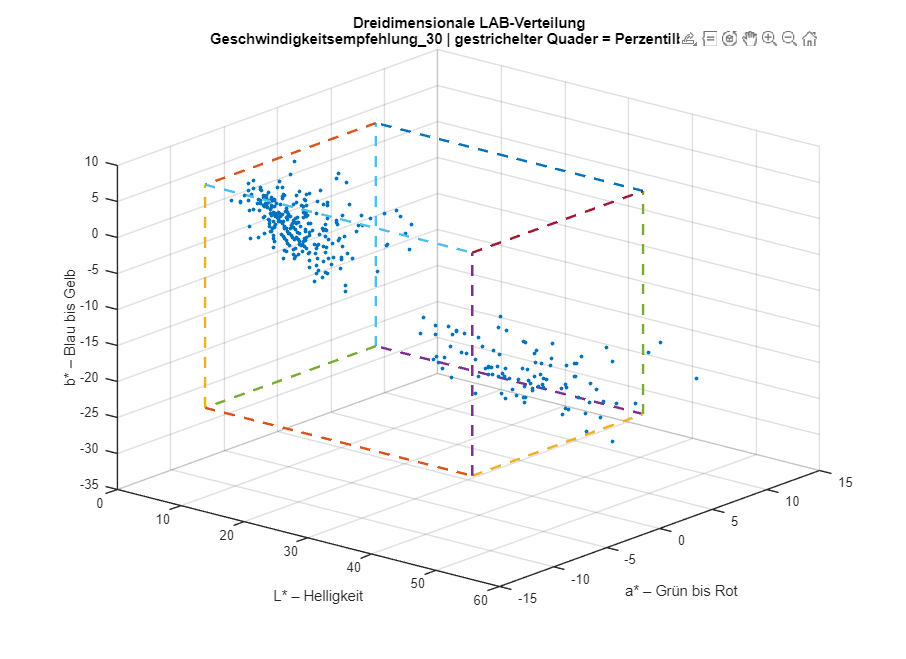

figLab = figure( ...
    "Name", ...
    "LAB-Verteilung", ...
    "NumberTitle", "off", ...
    "Position", [100, 80, 1100, 800]);

scatter3( ...
    labPlotValues(:,1), ...
    labPlotValues(:,2), ...
    labPlotValues(:,3), ...
    scatterPointSize, ...
    "filled");

hold on;

drawThresholdBox3D( ...
    roundedThreshold);

xlabel("L* – Helligkeit");
ylabel("a* – Grün bis Rot");
zlabel("b* – Blau bis Gelb");

title({ ...
    "Dreidimensionale LAB-Verteilung", ...
    categoryName + ...
    " | gestrichelter Quader = Perzentilbereich" ...
}, ...
"Interpreter", "none");

grid on;
view(40, 25);
hold off;

saveFigureBothFormats( ...
    figLab, ...
    outputFolder, ...
    "LAB_3D");

## 15. Verteilung im L*-a*-Raum

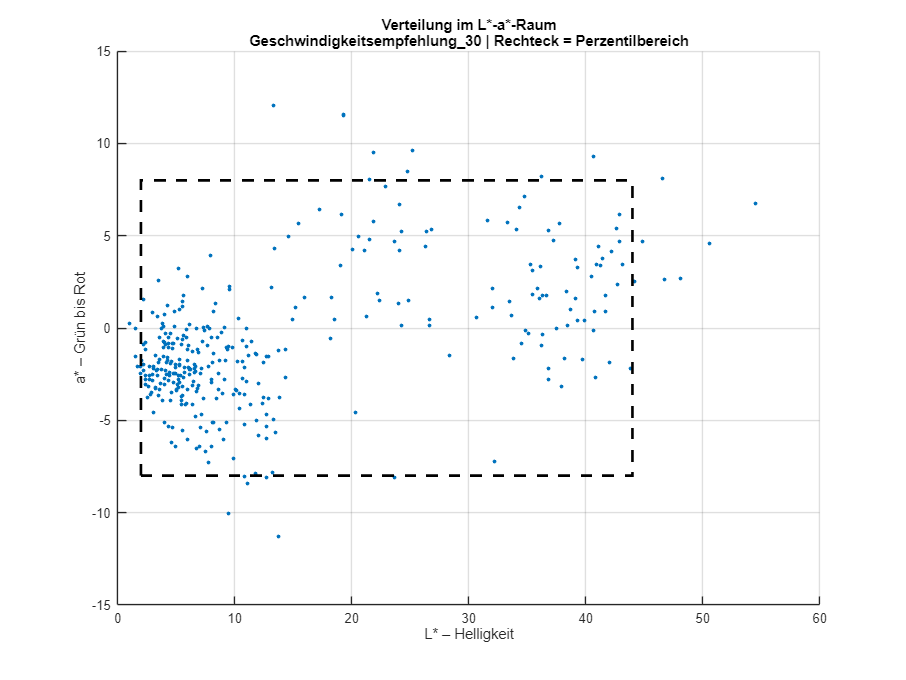

figLa = figure( ...
    "Name", ...
    "L-a-Verteilung", ...
    "NumberTitle", "off", ...
    "Position", [120, 100, 1000, 750]);

scatter( ...
    labPlotValues(:,1), ...
    labPlotValues(:,2), ...
    scatterPointSize, ...
    "filled");

hold on;

rectangle( ...
    "Position", ...
    [ ...
        roundedThreshold(1), ...
        roundedThreshold(3), ...
        roundedThreshold(2) - roundedThreshold(1), ...
        roundedThreshold(4) - roundedThreshold(3) ...
    ], ...
    "LineWidth", 2, ...
    "LineStyle", "--");

xlabel("L* – Helligkeit");
ylabel("a* – Grün bis Rot");

title({ ...
    "Verteilung im L*-a*-Raum", ...
    categoryName + ...
    " | Rechteck = Perzentilbereich" ...
}, ...
"Interpreter", "none");

grid on;
hold off;

saveFigureBothFormats( ...
    figLa, ...
    outputFolder, ...
    "LA_Verteilung");

## 16. Verteilung im L*-b*-Raum

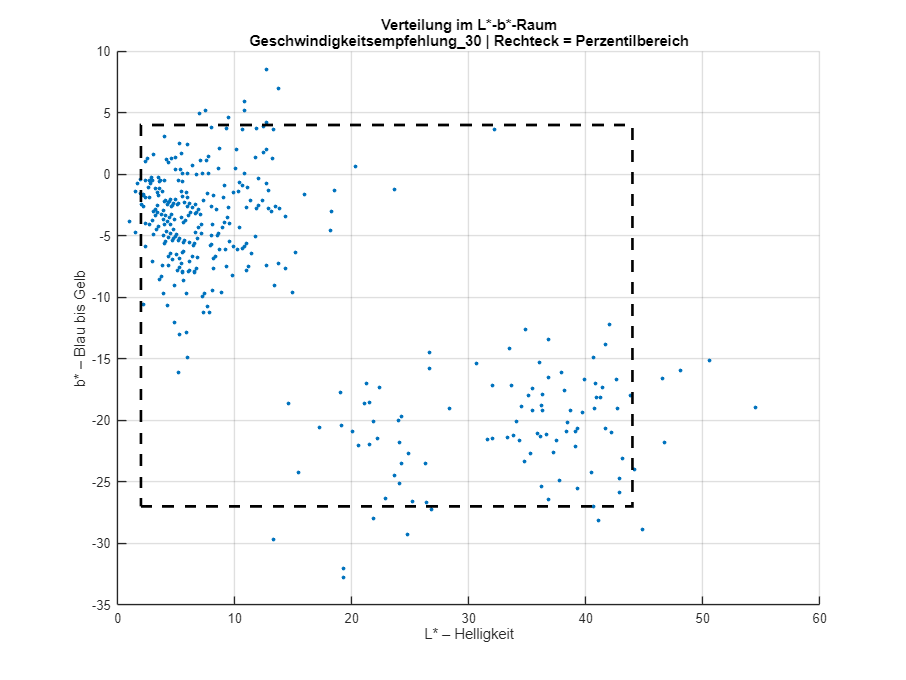

figLb = figure( ...
    "Name", ...
    "L-b-Verteilung", ...
    "NumberTitle", "off", ...
    "Position", [140, 120, 1000, 750]);

scatter( ...
    labPlotValues(:,1), ...
    labPlotValues(:,3), ...
    scatterPointSize, ...
    "filled");

hold on;

rectangle( ...
    "Position", ...
    [ ...
        roundedThreshold(1), ...
        roundedThreshold(5), ...
        roundedThreshold(2) - roundedThreshold(1), ...
        roundedThreshold(6) - roundedThreshold(5) ...
    ], ...
    "LineWidth", 2, ...
    "LineStyle", "--");

xlabel("L* – Helligkeit");
ylabel("b* – Blau bis Gelb");

title({ ...
    "Verteilung im L*-b*-Raum", ...
    categoryName + ...
    " | Rechteck = Perzentilbereich" ...
}, ...
"Interpreter", "none");

grid on;
hold off;

saveFigureBothFormats( ...
    figLb, ...
    outputFolder, ...
    "LB_Verteilung");

## 17. Verteilung im a*-b*-Raum

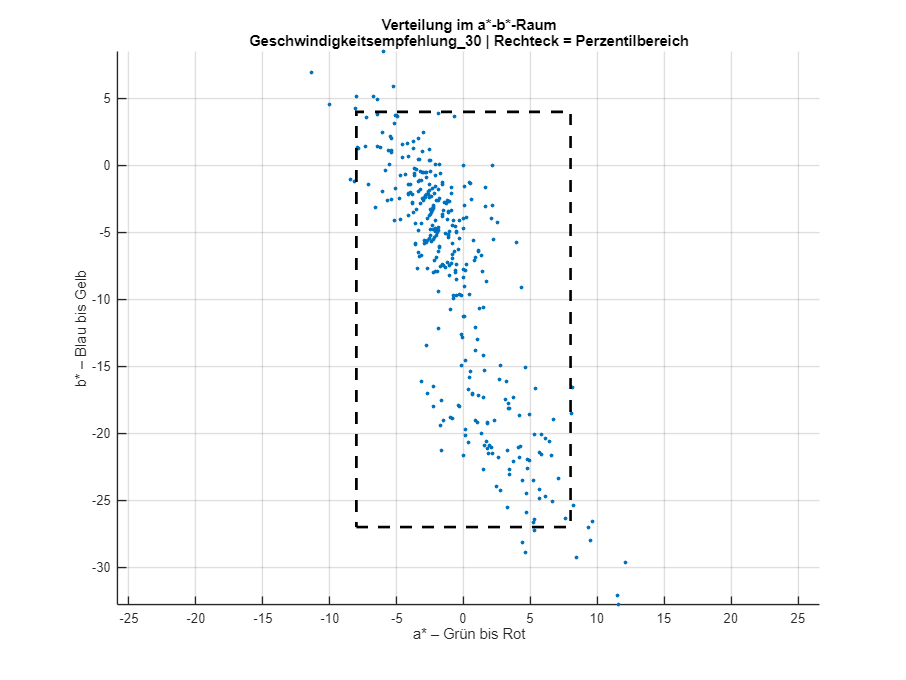

figAb = figure( ...
    "Name", ...
    "a-b-Verteilung", ...
    "NumberTitle", "off", ...
    "Position", [160, 140, 1000, 750]);

scatter( ...
    labPlotValues(:,2), ...
    labPlotValues(:,3), ...
    scatterPointSize, ...
    "filled");

hold on;

rectangle( ...
    "Position", ...
    [ ...
        roundedThreshold(3), ...
        roundedThreshold(5), ...
        roundedThreshold(4) - roundedThreshold(3), ...
        roundedThreshold(6) - roundedThreshold(5) ...
    ], ...
    "LineWidth", 2, ...
    "LineStyle", "--");

xlabel("a* – Grün bis Rot");
ylabel("b* – Blau bis Gelb");

title({ ...
    "Verteilung im a*-b*-Raum", ...
    categoryName + ...
    " | Rechteck = Perzentilbereich" ...
}, ...
"Interpreter", "none");

grid on;
axis equal;
hold off;

saveFigureBothFormats( ...
    figAb, ...
    outputFolder, ...
    "AB_Verteilung");

## 18. Histogramme der einzelnen LAB-Kanäle

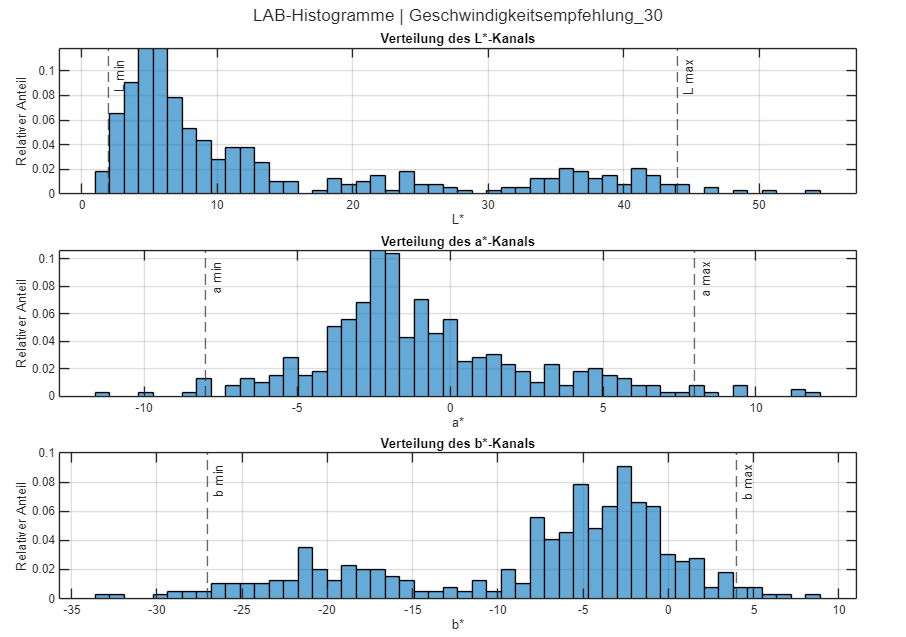

figHist = figure( ...
    "Name", ...
    "LAB-Histogramme", ...
    "NumberTitle", "off", ...
    "Position", [80, 50, 1200, 850]);

tiledlayout( ...
    3, ...
    1, ...
    "TileSpacing", "compact", ...
    "Padding", "compact");


% L*-Histogramm
nexttile;

histogram( ...
    labPlotValues(:,1), ...
    50, ...
    "Normalization", "probability");

hold on;

xline( ...
    roundedThreshold(1), ...
    "--", ...
    "L min");

xline( ...
    roundedThreshold(2), ...
    "--", ...
    "L max");

xlabel("L*");
ylabel("Relativer Anteil");
title("Verteilung des L*-Kanals");
grid on;
hold off;


% a*-Histogramm
nexttile;

histogram( ...
    labPlotValues(:,2), ...
    50, ...
    "Normalization", "probability");

hold on;

xline( ...
    roundedThreshold(3), ...
    "--", ...
    "a min");

xline( ...
    roundedThreshold(4), ...
    "--", ...
    "a max");

xlabel("a*");
ylabel("Relativer Anteil");
title("Verteilung des a*-Kanals");
grid on;
hold off;


% b*-Histogramm
nexttile;

histogram( ...
    labPlotValues(:,3), ...
    50, ...
    "Normalization", "probability");

hold on;

xline( ...
    roundedThreshold(5), ...
    "--", ...
    "b min");

xline( ...
    roundedThreshold(6), ...
    "--", ...
    "b max");

xlabel("b*");
ylabel("Relativer Anteil");
title("Verteilung des b*-Kanals");
grid on;
hold off;


sgtitle( ...
    "LAB-Histogramme | " + categoryName, ...
    "Interpreter", "none");

saveFigureBothFormats( ...
    figHist, ...
    outputFolder, ...
    "LAB_Histogramme");

## =========================================================

Funktion: Pixel in einem Bild interaktiv markieren ==========================================================

function [clickedX, clickedY, action] = markPixelsInImage( ...
    I, ...
    categoryName, ...
    imageFileName, ...
    selectionNumber, ...
    numberOfSelectedImages)

    clickedX = zeros(0,1);
    clickedY = zeros(0,1);

    markerHandles = gobjects(0,1);
    labelHandles = gobjects(0,1);

    action = 'continue';

    fig = figure( ...
        "Name", ...
        "Schildpixel markieren", ...
        "NumberTitle", "off", ...
        "Position", [80, 60, 1300, 850]);

    ax = axes( ...
        "Parent", fig);

    imshow( ...
        I, ...
        "Parent", ax, ...
        "InitialMagnification", "fit");

    hold(ax, "on");

    updateMarkingTitle( ...
        ax, ...
        categoryName, ...
        imageFileName, ...
        selectionNumber, ...
        numberOfSelectedImages, ...
        0);


    while true

        if ~ishandle(fig)
            action = 'q';
            return;
        end

        figure(fig);

        [x, y, button] = ginput(1);

        if ~ishandle(fig)
            action = 'q';
            return;
        end

## Enter: Bild abschließen

        if isempty(button) || button == 13
            break;
        end

## Linksklick: Pixel hinzufügen

        if button == 1

            xPixel = round(x);
            yPixel = round(y);

            if xPixel < 1 || ...
               xPixel > size(I,2) || ...
               yPixel < 1 || ...
               yPixel > size(I,1)

                continue;

            end

            clickedX(end+1,1) = ...
                xPixel;

            clickedY(end+1,1) = ...
                yPixel;

            markerHandles(end+1,1) = plot( ...
                ax, ...
                xPixel, ...
                yPixel, ...
                "r+", ...
                "MarkerSize", 14, ...
                "LineWidth", 2);

            labelHandles(end+1,1) = text( ...
                ax, ...
                xPixel + 2, ...
                yPixel - 2, ...
                sprintf("%d", numel(clickedX)), ...
                "Color", "r", ...
                "FontWeight", "bold", ...
                "FontSize", 9, ...
                "BackgroundColor", "w", ...
                "Margin", 1);

            updateMarkingTitle( ...
                ax, ...
                categoryName, ...
                imageFileName, ...
                selectionNumber, ...
                numberOfSelectedImages, ...
                numel(clickedX));

            continue;

        end

## Rechtsklick oder Backspace: letzte Markierung entfernen

        if button == 3 || button == 8

            if ~isempty(clickedX)

                if isgraphics(markerHandles(end))
                    delete(markerHandles(end));
                end

                if isgraphics(labelHandles(end))
                    delete(labelHandles(end));
                end

                markerHandles(end) = [];
                labelHandles(end) = [];

                clickedX(end) = [];
                clickedY(end) = [];

                updateMarkingTitle( ...
                    ax, ...
                    categoryName, ...
                    imageFileName, ...
                    selectionNumber, ...
                    numberOfSelectedImages, ...
                    numel(clickedX));

            end

            continue;

        end

## Tastaturbefehle

        if button == double('r') || ...
           button == double('R')

            delete(markerHandles( ...
                isgraphics(markerHandles)));

            delete(labelHandles( ...
                isgraphics(labelHandles)));

            markerHandles = gobjects(0,1);
            labelHandles = gobjects(0,1);

            clickedX = zeros(0,1);
            clickedY = zeros(0,1);

            updateMarkingTitle( ...
                ax, ...
                categoryName, ...
                imageFileName, ...
                selectionNumber, ...
                numberOfSelectedImages, ...
                0);

        elseif button == double('n') || ...
               button == double('N')

            clickedX = zeros(0,1);
            clickedY = zeros(0,1);
            break;

        elseif button == double('q') || ...
               button == double('Q')

            action = 'q';
            break;

        end

    end


    if ishandle(fig)
        close(fig);
    end

end

%% =========================================================
% Funktion: Titel im Markierungsfenster aktualisieren
% ==========================================================

function updateMarkingTitle( ...
    ax, ...
    categoryName, ...
    imageFileName, ...
    selectionNumber, ...
    numberOfSelectedImages, ...
    numberOfClicks)

    % Alle Titelzeilen ausdrücklich als Character-Vektoren erzeugen
    firstLine = sprintf( ...
        '%s | Datei: %s', ...
        char(categoryName), ...
        char(imageFileName));

    secondLine = sprintf( ...
        'Bild %d von %d | Markierungen: %d', ...
        selectionNumber, ...
        numberOfSelectedImages, ...
        numberOfClicks);

    thirdLine = ...
        'Linksklick = markieren | Rechtsklick/Backspace = zurück';

    fourthLine = ...
        'Enter = fertig | R = löschen | N = überspringen | Q = beenden';

    title( ...
        ax, ...
        { ...
            firstLine; ...
            secondLine; ...
            thirdLine; ...
            fourthLine ...
        }, ...
        'Interpreter', ...
        'none', ...
        'FontSize', ...
        11);

end
% Funktion: Ergebnistabelle der markierten Pixel erzeugen 
function resultTable = createPixelResultTable( ...
    imageNames, ...
    imageNumbers, ...
    clickNumbers, ...
    xValues, ...
    yValues, ...
    rgbR, ...
    rgbG, ...
    rgbB, ...
    labL, ...
    labA, ...
    labB)

    resultTable = table( ...
        imageNames, ...
        imageNumbers, ...
        clickNumbers, ...
        xValues, ...
        yValues, ...
        rgbR, ...
        rgbG, ...
        rgbB, ...
        labL, ...
        labA, ...
        labB, ...
        'VariableNames', ...
        { ...
            'Bildname', ...
            'Bildnummer', ...
            'Markierung', ...
            'PixelX', ...
            'PixelY', ...
            'RGB_R', ...
            'RGB_G', ...
            'RGB_B', ...
            'LAB_L', ...
            'LAB_A', ...
            'LAB_B' ...
        });

end

## =========================================================

Funktion: Teilmenge für Diagramme auswählen ==========================================================

function plotValues = selectPlotPixels( ...
    labValues, ...
    maxPlotPixels)

    numberOfPixels = ...
        size(labValues, 1);

    if numberOfPixels <= maxPlotPixels

        plotValues = ...
            labValues;

    else

        selectedIndices = randperm( ...
            numberOfPixels, ...
            maxPlotPixels);

        plotValues = labValues( ...
            selectedIndices, ...
            :);

    end

end

## =========================================================

Funktion: Perzentilquader im LAB-Raum zeichnen ==========================================================

function drawThresholdBox3D(threshold)

    Lmin = threshold(1);
    Lmax = threshold(2);

    Amin = threshold(3);
    Amax = threshold(4);

    Bmin = threshold(5);
    Bmax = threshold(6);

    vertices = [
        Lmin, Amin, Bmin;
        Lmax, Amin, Bmin;
        Lmax, Amax, Bmin;
        Lmin, Amax, Bmin;
        Lmin, Amin, Bmax;
        Lmax, Amin, Bmax;
        Lmax, Amax, Bmax;
        Lmin, Amax, Bmax
    ];

    edges = [
        1, 2;
        2, 3;
        3, 4;
        4, 1;
        5, 6;
        6, 7;
        7, 8;
        8, 5;
        1, 5;
        2, 6;
        3, 7;
        4, 8
    ];

    for edgeNumber = 1:size(edges,1)

        firstVertex = ...
            vertices(edges(edgeNumber,1), :);

        secondVertex = ...
            vertices(edges(edgeNumber,2), :);

        plot3( ...
            [firstVertex(1), secondVertex(1)], ...
            [firstVertex(2), secondVertex(2)], ...
            [firstVertex(3), secondVertex(3)], ...
            "--", ...
            "LineWidth", 1.8);

    end

end

## =========================================================

Funktion: Figur als PNG und FIG speichern ==========================================================

function saveFigureBothFormats( ...
    fig, ...
    outputFolder, ...
    baseFileName)

    pngFile = fullfile( ...
        outputFolder, ...
        baseFileName + ".png");

    figFile = fullfile( ...
        outputFolder, ...
        baseFileName + ".fig");

    saveas( ...
        fig, ...
        pngFile);

    savefig( ...
        fig, ...
        figFile);

end